%% This file makes use of the following functions from Matlab Functions Library
imagedata
ImagingResonanceFit

filenames_s1 = {};
imgfreqs_s1 = [];
filenames_s2 = {};
imgfreqs_s2 = [];

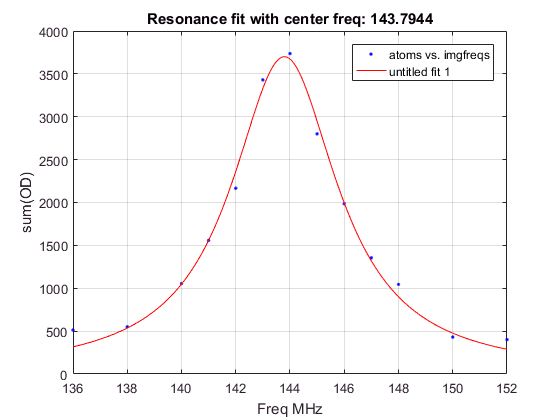

atoms_s1 = zeros(size(filenames_s1));
for i = 1:length(filenames_s1)
    temp = imagedata(filenames_s1{i},'crop',{'rect',271,218,135,300},'bg',{'avg',20},'plot',{0}); %,'Nsat',630
    atoms_s1(i) = sum(sum(temp.od2));
end
fitres_s1 = ImagingResonanceFit(imgfreqs_s1,atoms_s1);


% save([datestr(datetime,'yyyy-mm-dd'),'-State1-ImgRes-Data.mat'],'filenames_s1','imgfreqs_s1');

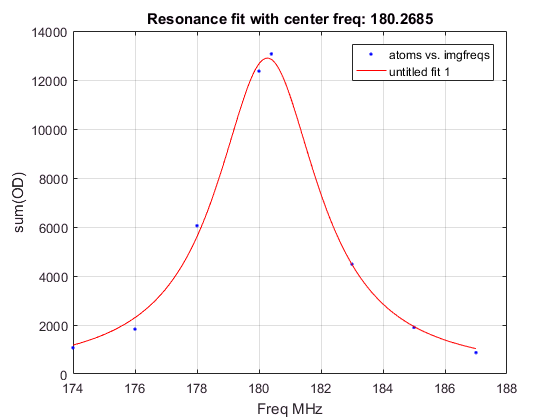

atoms_s2 = zeros(size(filenames_s2));
for i = 1:length(filenames_s2)
    temp = imagedata(filenames_s2{i},'crop',{'rect',124,334,135,300},'bg',{'avg',20},'plot',{0},'Nsat',630);
    atoms_s2(i) = sum(sum(temp.od2));
end
fitres_s2 = ImagingResonanceFit(imgfreqs_s2,atoms_s2);


% save([datestr(datetime,'yyyy-mm-dd'),'-State2-ImgRes-Data.mat'],'filenames_s2','imgfreqs_s2');